clc
clear 
close all
load atheta.mat
true_theta = atheta(223:223+85);
dt = 0.018;
t0 = 0:dt:size(true_theta,1)*dt-dt;
subplot(2,2,1)
plot(t0,atheta(223:223+85),"b*")
title("true")
subplot(2,2,3)
plot(223:223+84,diff(true_theta))

% 定义参数
total_length = 139;
step_size = 0.01;
noise_range = [-0.0005, 0.0005];
loss_probability = 0.0005;
start_time = 1;
% 计算步数
num_steps = total_length * step_size;

% 生成时间向量
t0 = start_time+0:step_size:start_time+num_steps-step_size;

% 添加随机噪声
noise = (noise_range(2) - noise_range(1)) * rand(size(t0)) + noise_range(1);
t0 = t0 + noise;

% 随机丢失数据
lost_indices = rand(size(t0)) < loss_probability;
t0(lost_indices) = [];



a = (1.045-0.780)*rand() + 0.780;

omega = 0*(2-1.884)*rand() + 1.884;
phi = 2*pi*rand(1,1);

fn =@(t) -a./omega *cos(omega*t+phi)+(2.090-a)*t;
theta = mod(fn(t0)+ 0.05*pi*randn(1,length(t0)),2*pi);


A= a*sin(step_size/2);
D= (2.090-a)*step_size;
2*A+D

ans = 0.0209

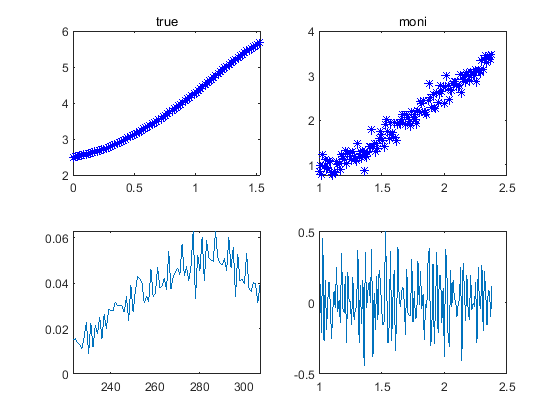

subplot(2,2,2)
plot(t0,theta,"b*")
title("moni")
subplot(2,2,4)
plot(t0(2:end),diff(theta))